# **Polar Codes**

**Encoding and Decoding with Performance Analysis**

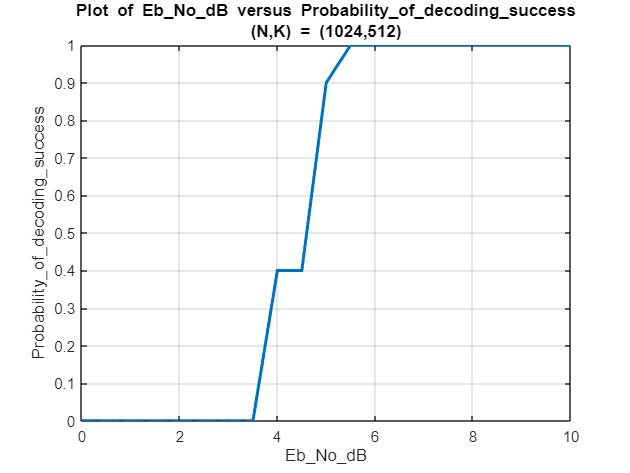

clearvars;
close all;
clc;

tic
load('Reliability_Sequence.mat');
N = 1024;
n = log2(N);
K = 512;

Sequence = Reliability_Sequence(Reliability_Sequence <= N);
Frozen_bits = Sequence(1:N-K);

Nsim = 10;
Eb_No_Range = 0:0.5:10;
Probability_of_decoding_success = zeros(1, length(Eb_No_Range));
Bit_Error_Rate = zeros(1, length(Eb_No_Range));
Block_Errors_Rate = zeros(1, length(Eb_No_Range));
Iteration_index = 1;

for Eb_No = Eb_No_Range
    Successful_Decoding = 0;
    Nsim_block_errors = 0; 
    Nsim_bit_errors = 0;

    for block = 1:Nsim
        message_sequence = randi([0 1], 1, K);
        message = zeros(1, N);
        message(Sequence(N-K+1:end)) = message_sequence;
        
        code_word = Polar_Encoding(message, n);
        code_word = BPSK_AWGN_Introduction(code_word, Eb_No, K, N);
        
        global L;
        global ucap;
        global nodes;
        
        L = zeros(n+1,N);
        L(1,:) = code_word;
        ucap = zeros(n+1,N);
        nodes = zeros(n+1,1);
        
        polar_decode(code_word, 1, n, Frozen_bits);
        message_cap = ucap(n+1, Sequence(N-K+1:end));
   
        Evident_errors = sum(message_sequence ~= message_cap);
        if(Evident_errors == 0)
            Successful_Decoding = Successful_Decoding + 1;
        else
            Nsim_bit_errors = Nsim_bit_errors + Evident_errors;
            Nsim_block_errors = Nsim_block_errors + 1;
        end
    end

    Probability_of_decoding_success(Iteration_index) = (1/Nsim)*Successful_Decoding;
    Bit_Error_Rate(Iteration_index) = Nsim_bit_errors/K/Nsim;
    Block_Errors_Rate(Iteration_index) = Nsim_block_errors/Nsim;
    Iteration_index = Iteration_index + 1;
end

plot(Eb_No_Range, Probability_of_decoding_success, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Probability\_of\_decoding\_success" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Probability\_of\_decoding\_success');
grid on;

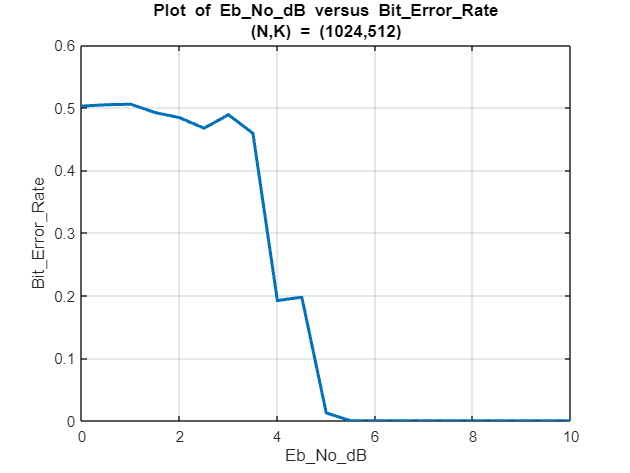

plot(Eb_No_Range, Bit_Error_Rate, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Bit\_Error\_Rate" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Bit\_Error\_Rate');
grid on;

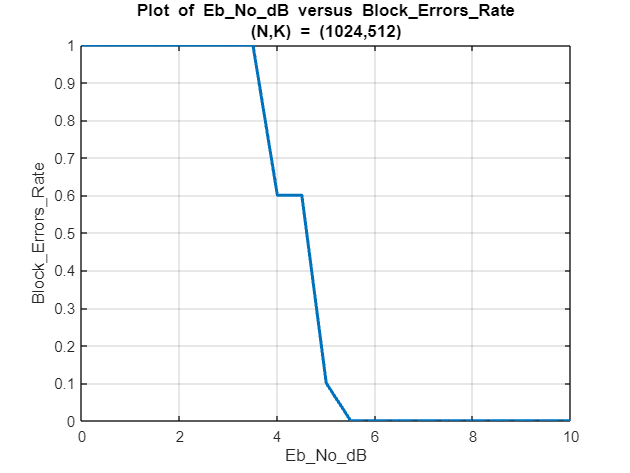

plot(Eb_No_Range, Block_Errors_Rate, 'LineWidth', 2);
title("Plot of Eb\_No\_dB versus Block\_Errors\_Rate" + newline + "(N,K) = (" + num2str(N) + "," + num2str(K) + ")");
xlabel('Eb\_No\_dB');
ylabel('Block\_Errors\_Rate');
grid on;

toc

Elapsed time is 14.944900 seconds.


function code_word = Polar_Encoding(message, bit_length)
    Generator_Matrix = [1 0; 1 1];
    A = Generator_Matrix;
    B = Generator_Matrix;
    for count = 1:bit_length-1
       A = kron(A, B);
    end
    Generator_Matrix = A;
    code_word = mod(message*Generator_Matrix, 2);
end

function code_word = BPSK_AWGN_Introduction(code_word, Eb_No_dB, K, N)
    BPSK_modulated_code_word = 1 - 2*code_word;
    Eb_No = 10^(Eb_No_dB/10);
    Es_No = (K/N) * Eb_No;
    sigma = sqrt(1 / Es_No);
    AWGN = sigma*randn(1, N);
    
    code_word = BPSK_modulated_code_word + AWGN;
end

function polar_decode(received_bits,depth,n,Frozen_bits)
    global L;
    global ucap;
    global nodes;

    f=@(r1,r2) sign(r1).*sign(r2).*min(abs(r1),abs(r2));
    g=@(r1,r2,c)r2+(1-2*c).*r1;
    node = nodes(depth);

    if depth == n+1
        nodes(depth) = nodes(depth) + 1;
        if any(Frozen_bits == (node+1)) 
            ucap(n+1,node+1) = 0; 
        else 
            if L(n+1,node+1) >= 0 
                ucap(n+1,node+1) = 0; 
            else 
                ucap(n+1,node+1) = 1; 
            end 
       end 
       return;
    end

    temp=2^(n-depth+1);
    a = received_bits(1:temp/2);
    b = received_bits(temp/2+1:end);
    L(depth+1,temp/2*node+1:temp/2*(node+1)) = f(a,b);
    new_set = f(a,b);
    nodes(depth) = nodes(depth) + 1;
    polar_decode(new_set, depth+1, n, Frozen_bits);

    ucap_left = ucap(depth+1, temp/2*node+1:temp/2*(node+1));
    node = nodes(depth);
    L(depth+1, temp/2*node+1:temp/2*(node+1)) = g(a,b,ucap_left);
    nodes(depth) = nodes(depth) + 1;
    new_set_2 = g(a,b,ucap_left);
    polar_decode(new_set_2,depth+1,n,Frozen_bits);

    ucap_right = ucap(depth+1,temp/2*node+1:temp/2*(node+1));
    ucap_left = ucap(depth+1,(((temp/2)*node)-(temp/2)+1):temp/2*(node));
    ucap(depth, (((temp/2)*node)-(temp/2)+1):temp/2*(node+1)) = [mod(ucap_left + ucap_right, 2) ucap_right];
end